# Sistema de filtragem

clearvars

## Recolha de dados

filename = "domingues1_perna.csv";
data_table = readtable(filename,"VariableNamingRule","preserve");
data_set_z = table2array(data_table(:,"z_accel"));
data_time = table2array(data_table(:,"Hours:Minutes:Seconds.Milliseconds"));
data_time = seconds(data_time); data_time = data_time - data_time(1);

% bitalino_Fs = 100;
% data_table = readtable("domingues_coxis_03.txt");
% data_set_z = table2array(data_table(:,"Var6"));
% data_time = linspace(0,length(data_set_z)/bitalino_Fs,length(data_set_z))';

## Frequência

L = length(data_time);

Fs = mean(1./diff(data_time));
disp("Sampling rate: " + Fs + "Hz")

Sampling rate: 61.4671Hz



f = Fs*(0:(L/2))/L;

## Z_DATA

fft_z = fft(data_set_z - mean(data_set_z));

#### Plots

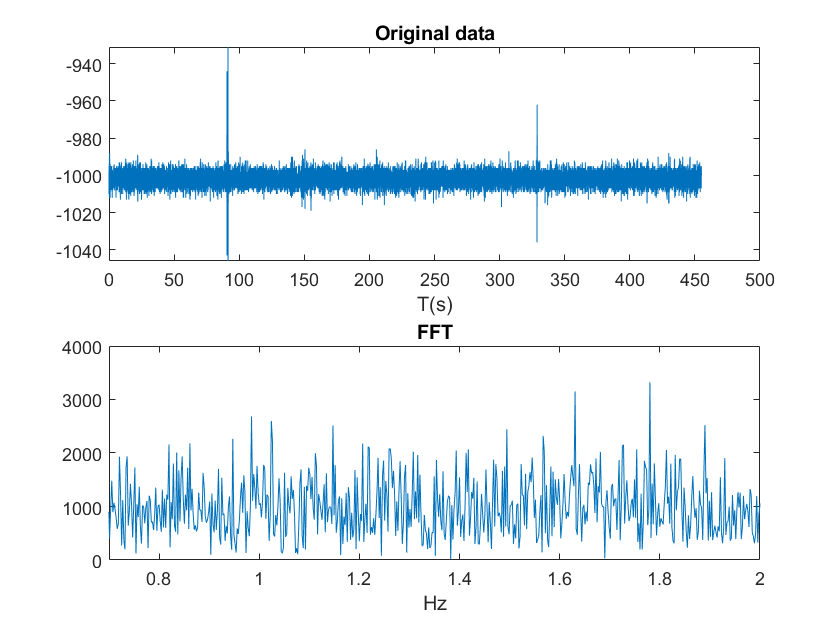

figure,
subplot(211),plot(data_time, data_set_z)
title("Original data"),xlabel("T(s)")
subplot(212),plot(f, abs(fft_z(1:numel(f)))*2)
title("FFT"),xlim([0.7, 2]),xlabel("Hz")

### Remove outliers

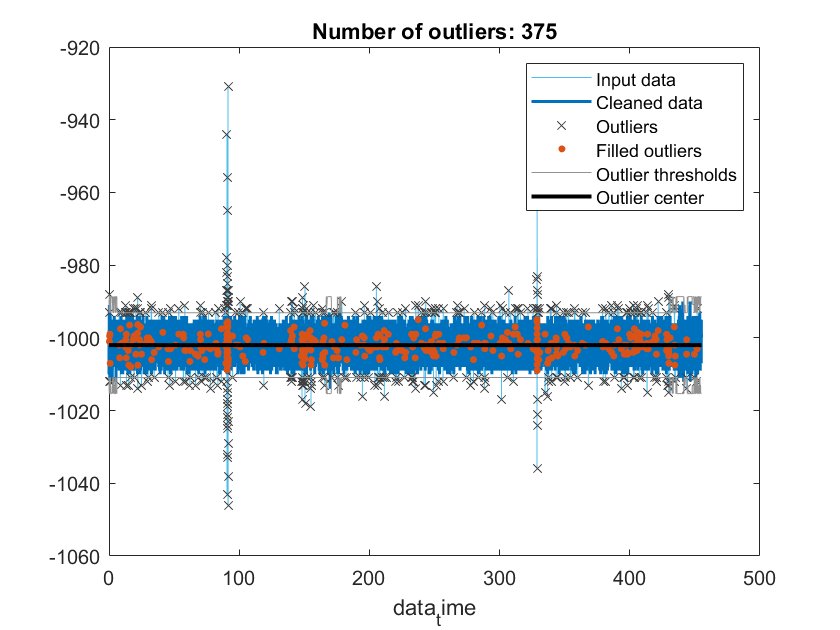

% Fill outliers
[outliers,outlierIndices,thresholdLow,thresholdHigh,center] = ...
    filloutliers(data_set_z,"linear","movmedian",60,"SamplePoints",data_time);

% Display results
clf
plot(data_time,data_set_z,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on
plot(data_time,outliers,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(data_time(outlierIndices),data_set_z(outlierIndices),"x",...
    "Color",[64 64 64]/255,"DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices))

% Plot filled outliers
plot(data_time(outlierIndices),outliers(outlierIndices),".","MarkerSize",12,...
    "Color",[217 83 25]/255,"DisplayName","Filled outliers")

% Plot outlier thresholds
plot([data_time(:); missing; data_time(:)],...
    [thresholdHigh(:); missing; thresholdLow(:)],"Color",[145 145 145]/255,...
    "DisplayName","Outlier thresholds")

% Plot outlier center
plot(data_time,center,"k","LineWidth",2,"DisplayName","Outlier center")

hold off
legend
xlabel("data_time")

clear outlierIndices thresholdLow thresholdHigh center

#### Plots

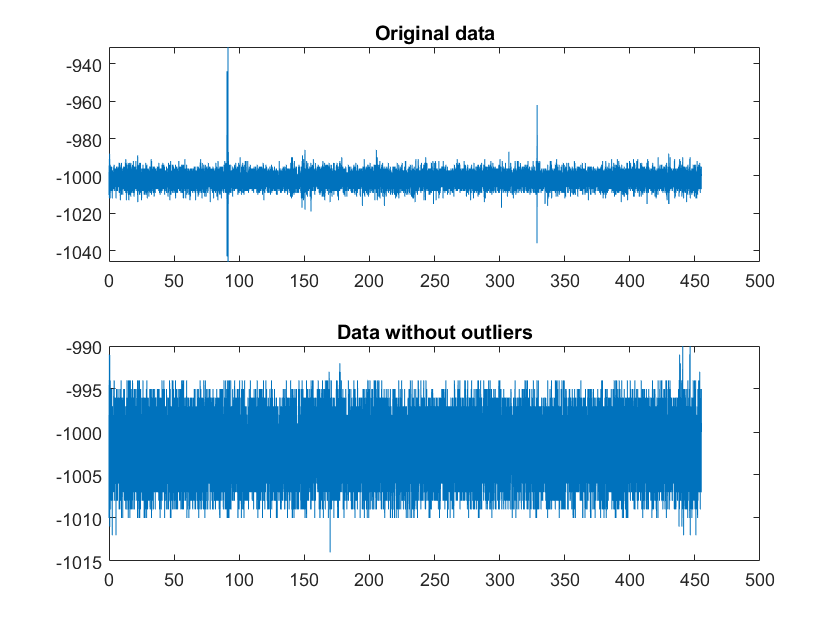

figure,
subplot(211),plot(data_time, data_set_z)
title("Original data")
subplot(212),plot(data_time, outliers)
title("Data without outliers")


fft_outliers = fft(outliers - mean(outliers));


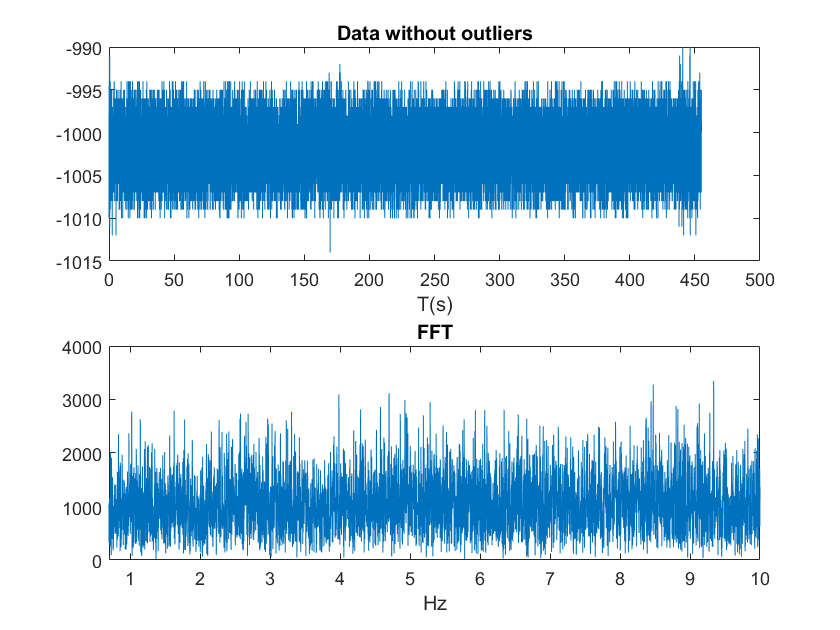

% Smooth input data
smoothedData = smoothdata(fft_outliers,"movmean",5);

figure,
subplot(211),plot(data_time, outliers)
title("Data without outliers"),xlabel("T(s)")
subplot(212),plot(f, abs(fft_outliers(1:numel(f)))*2)
title("FFT"),xlim([0.7, 10]),xlabel("Hz")

### Bandpass filter [0.7 - 10]Hz

% Hd = butter_ecg(Fs);
% filtered = filter(Hd,outliers);
filtered = filter_bpm(outliers);

#### Plots

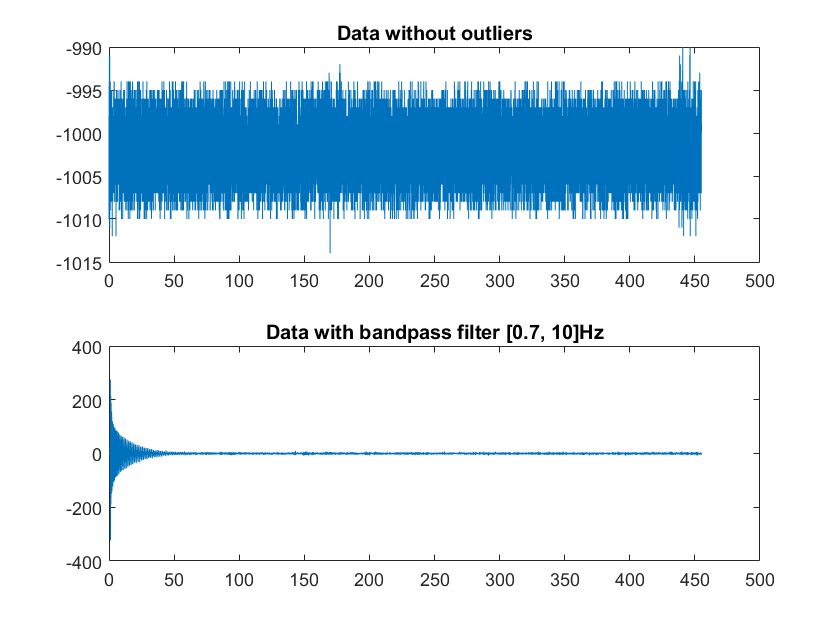

figure,
subplot(211),plot(data_time, outliers)
title("Data without outliers")
subplot(212),plot(data_time, filtered)
title("Data with bandpass filter [0.7, 10]Hz")

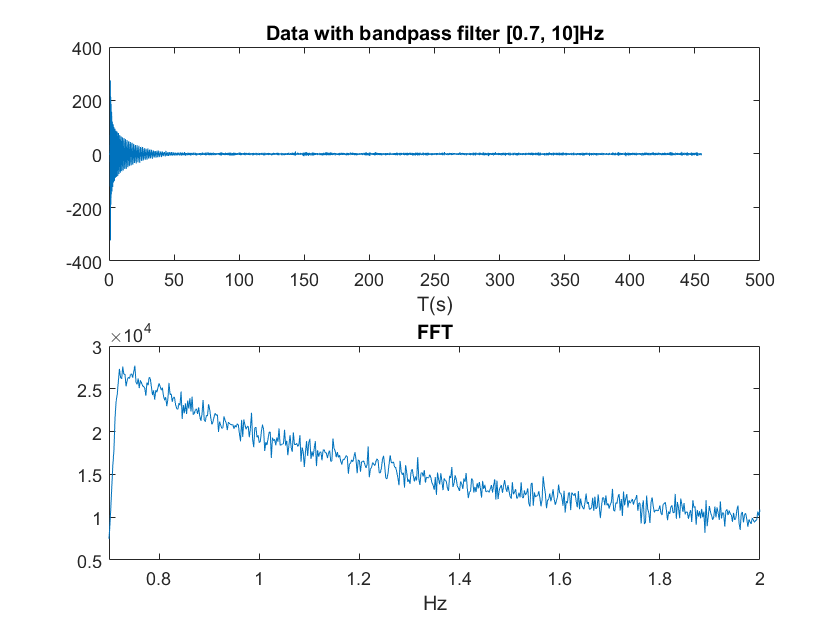


fft_filtered = fft(filtered);

figure,
subplot(211),plot(data_time, filtered)
title("Data with bandpass filter [0.7, 10]Hz"),xlabel("T(s)")
subplot(212),plot(f, abs(fft_filtered(1:numel(f)))*2)
title("FFT"),xlim([0.7, 2]),xlabel("Hz")

[~, I] = max(abs(fft_filtered(1:numel(f)))*2);
disp("Estimated frequency: " + f(I) + "Hz")

Estimated frequency: 0.75164Hz


disp("Estimated BPM: " + f(I)*60)

Estimated BPM: 45.0981


### Segmentation and Windowing

#### Segmentation

samples_15s = round(Fs*15);
samples_60s = samples_15s * 4;
[segmented, time_array] = segment_data(filtered,data_time,samples_60s,samples_15s);

f_segment = Fs*(0:(samples_60s/2))/samples_60s;

n = size(segmented,2)

n = 26

#### Windowing

windowed = hamming(samples_60s,"symmetric") .* segmented;

#### BPM

fft_windows = fft(windowed);

index_7 = find(f_segment>.7,1)

index_7 = 43

index_100 = find(f_segment<2,1,"last")

index_100 = 120

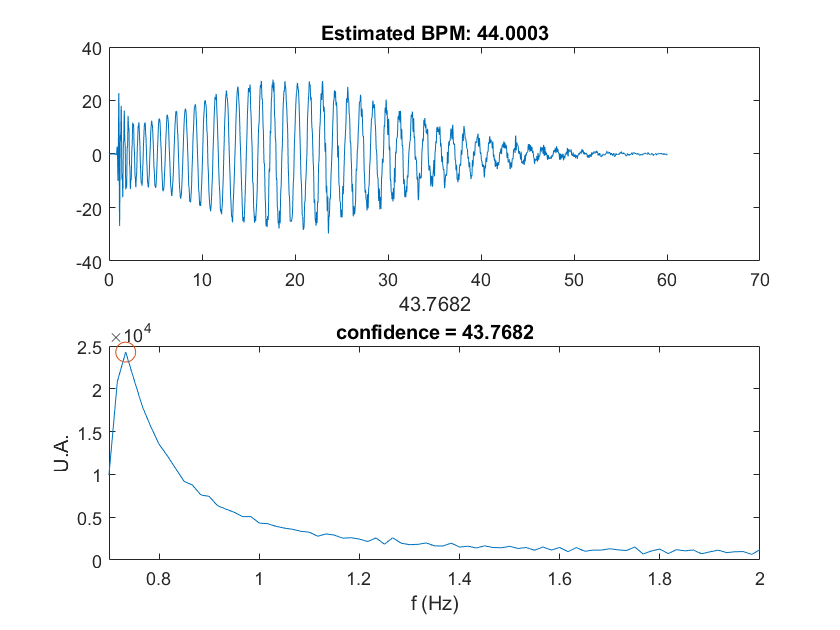

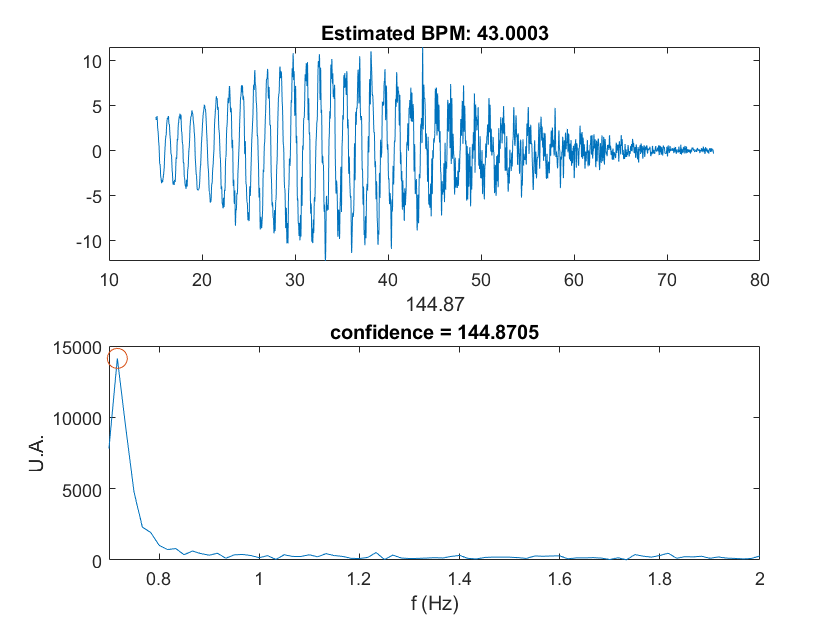

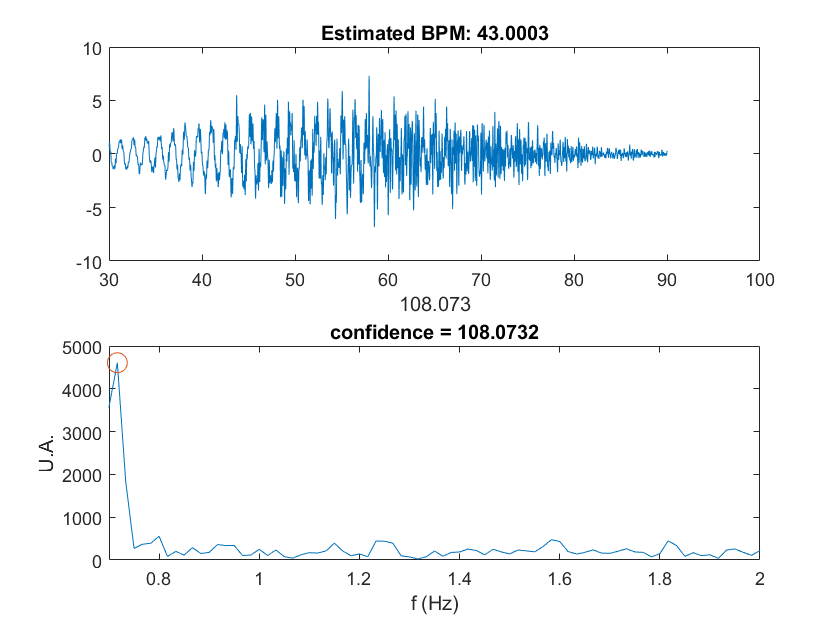

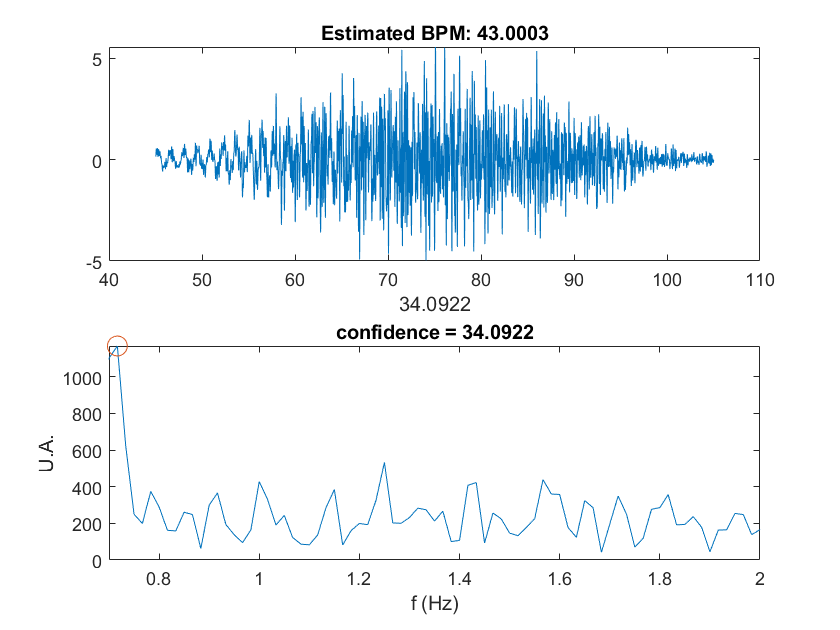

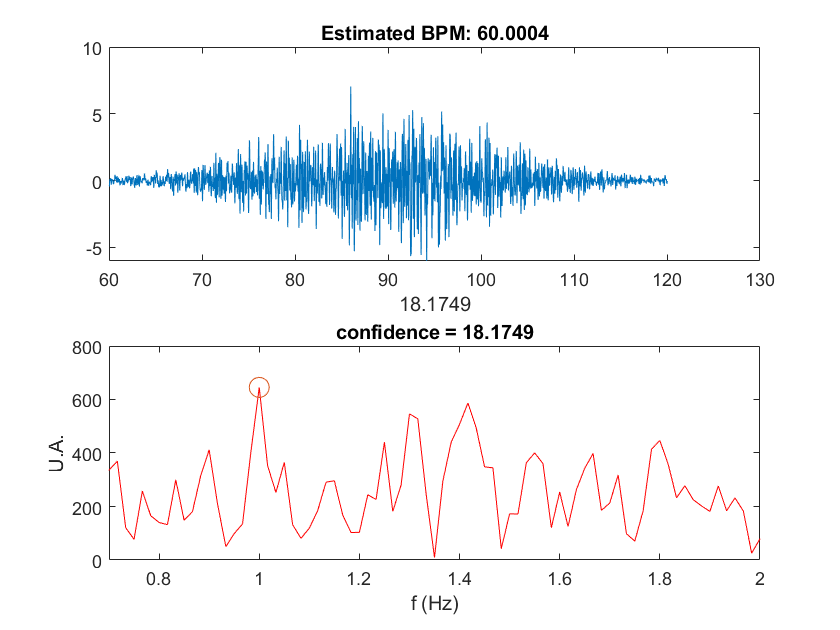

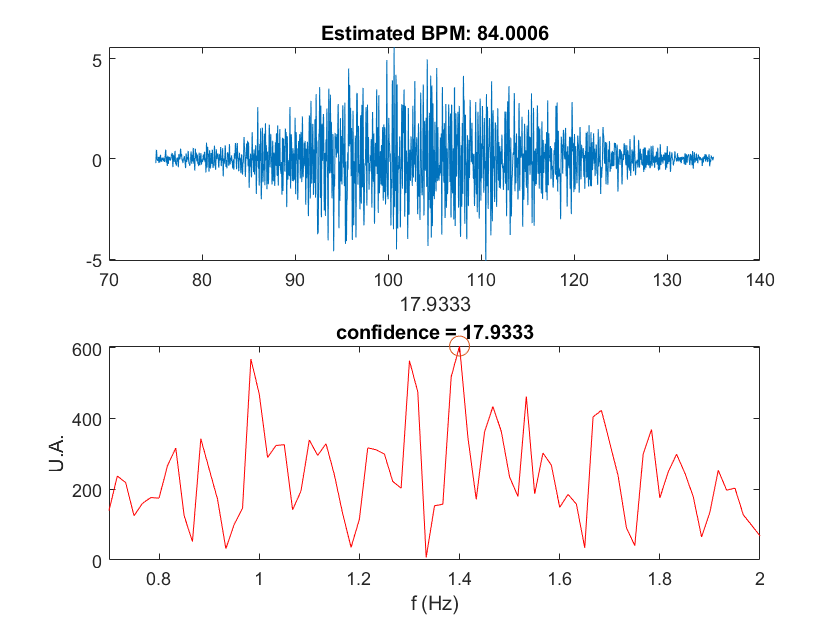

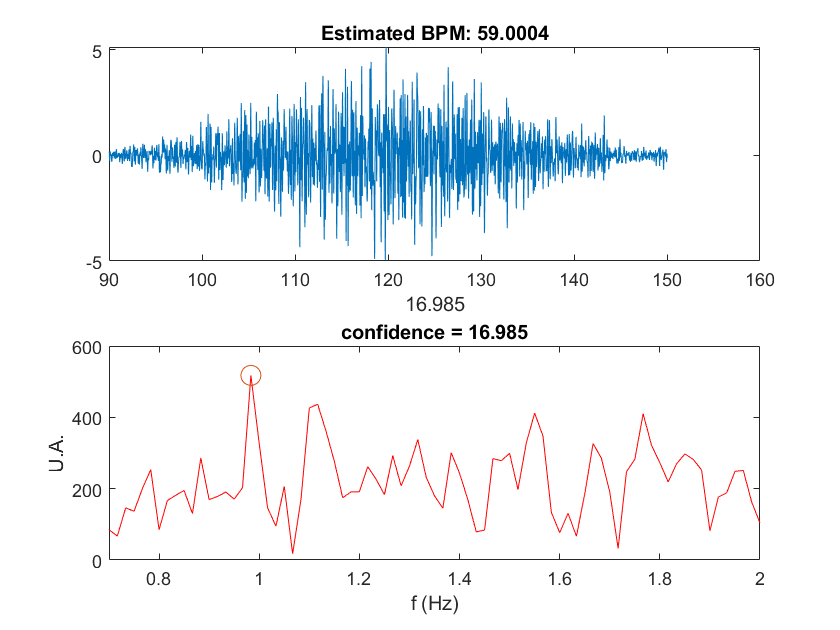

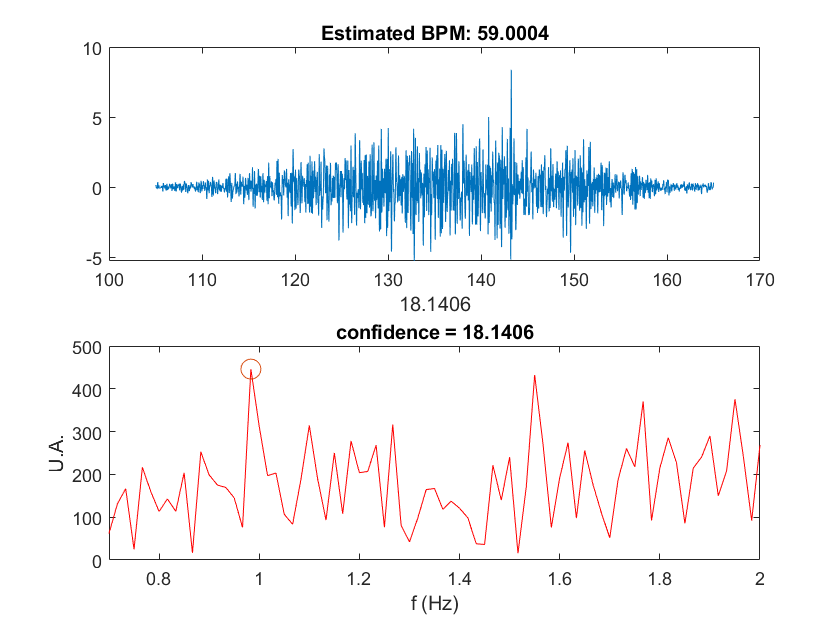


bpms = zeros(1,n);
figure
for count = 1:n
    figure
    fft_cut = fft_windows(1:numel(f_segment),count);
    [M, I] = max(abs(fft_cut(index_7:index_100))*2);
    bpms(count) = f_segment(I+index_7-1)*60;
    
    subplot(211)
    plot(time_array(:,count),windowed(:,count))
    title("Estimated BPM: "+bpms(count))
    conf = confidence(fft_windows(1:numel(f_segment),count),f_segment,0.7,2);
    xlabel(conf)
    
    subplot(212)
    
    if conf > 25
        plot(f_segment, abs(fft_cut)*2)
    else
        plot(f_segment, abs(fft_cut)*2, "r")
    end
    xlim([0.7, 2])
    title("confidence = " + conf)
    xlabel("f (Hz)"),ylabel("U.A.")
    
    hold on
    plot(f_segment(I+index_7-1), M, 'o', 'MarkerSize', 10)
end

## Hilbert Transform

ht_data = abs(hilbert(windowed)).^2;

## Fourier Transform

fft_data = fft(ht_data);

#### BPM

bpms = zeros(1,n);

index_7 = find(f_segment>.7,1)

index_7 = 43

index_100 = find(f_segment<2,1,"last")

index_100 = 120

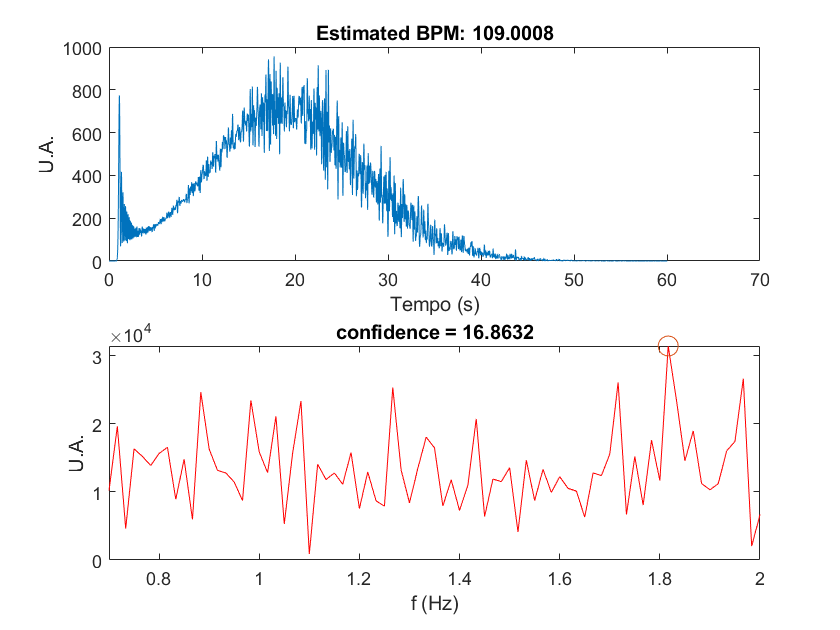

--------------------------------------------------------------------------


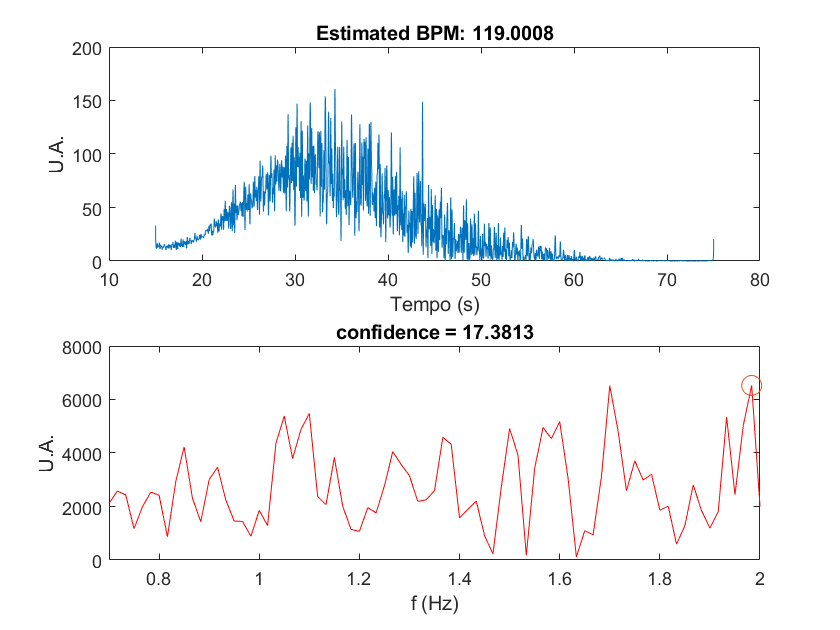

--------------------------------------------------------------------------


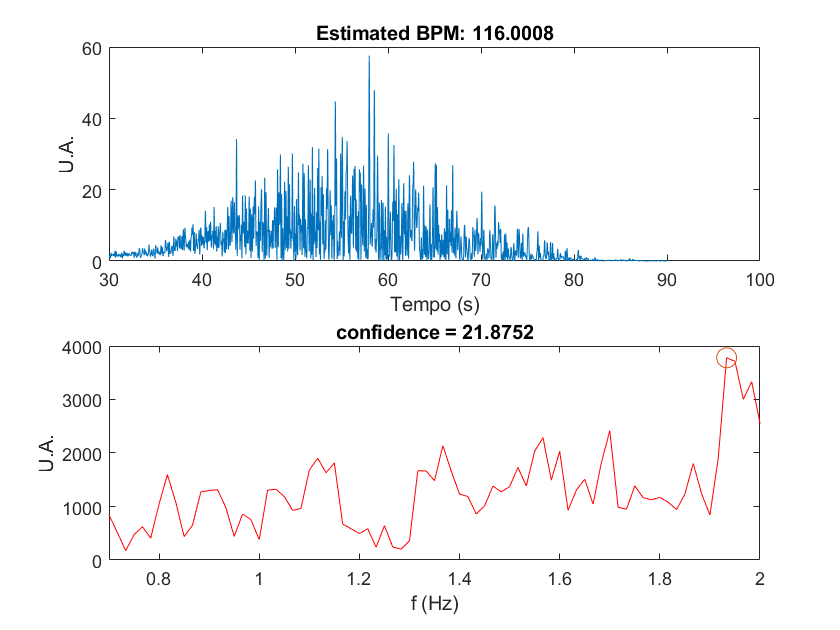

--------------------------------------------------------------------------


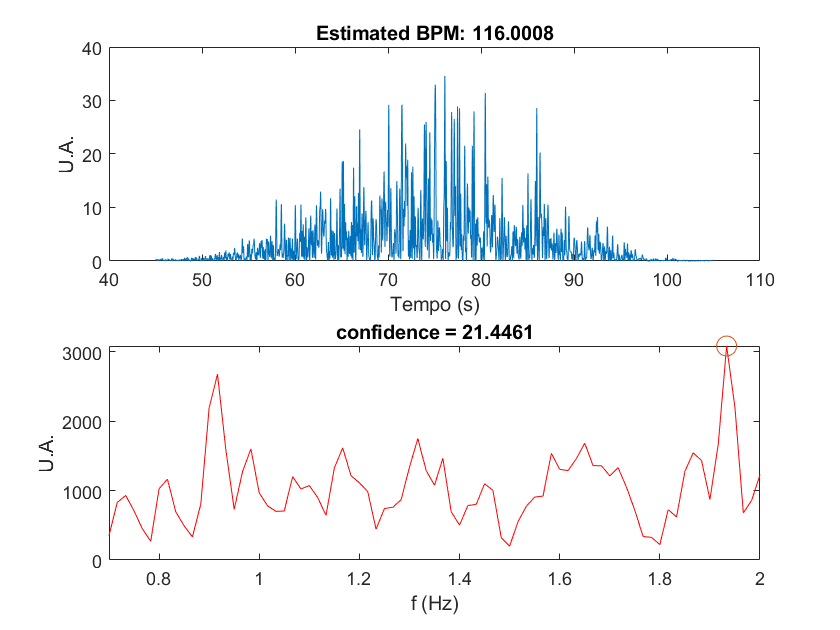

--------------------------------------------------------------------------


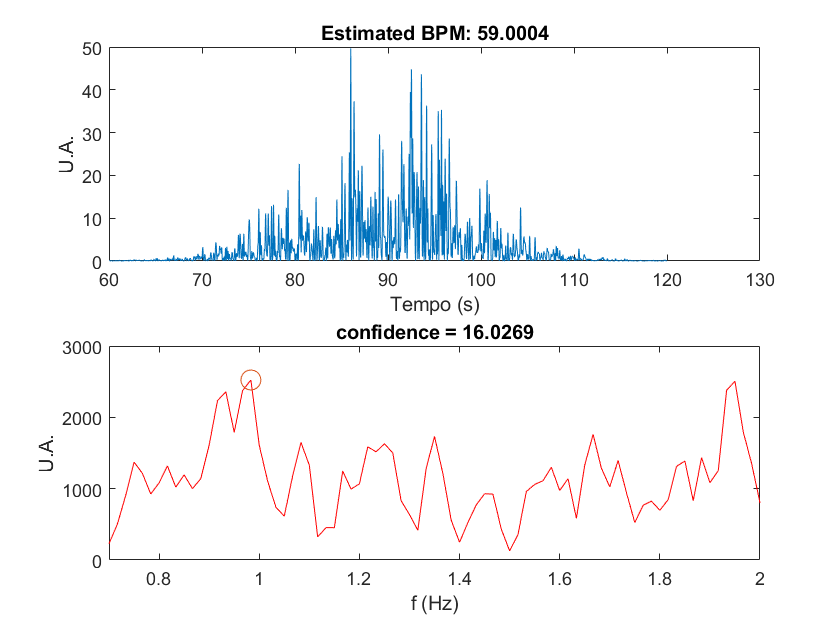

--------------------------------------------------------------------------


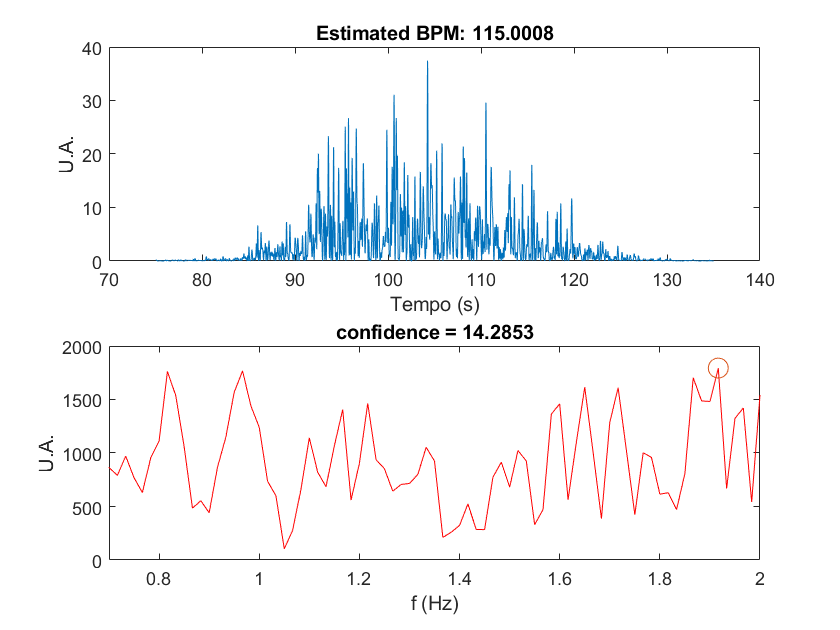

--------------------------------------------------------------------------


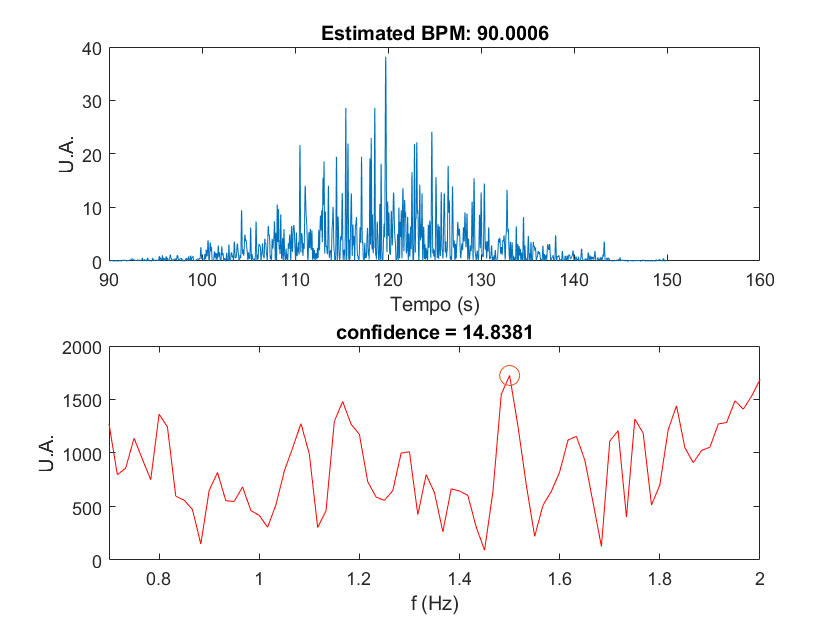

--------------------------------------------------------------------------


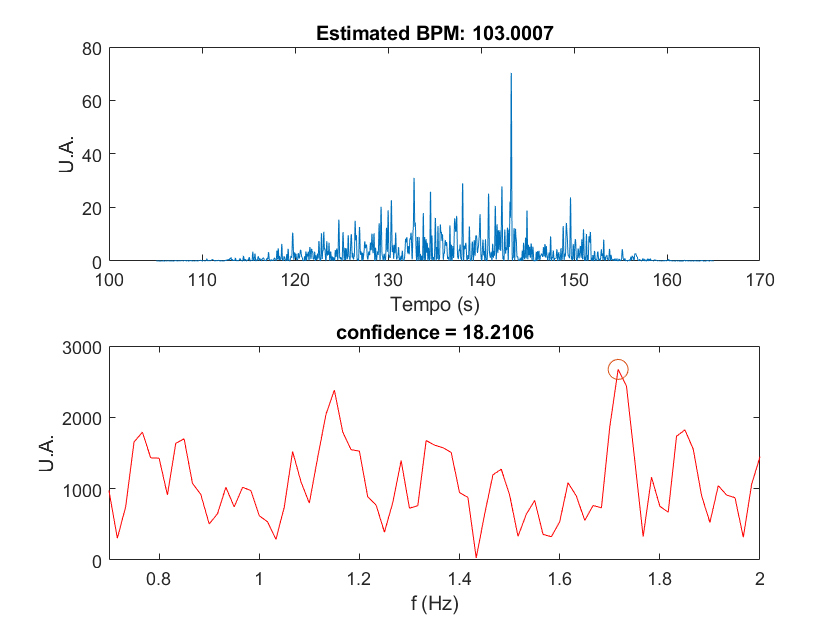

--------------------------------------------------------------------------


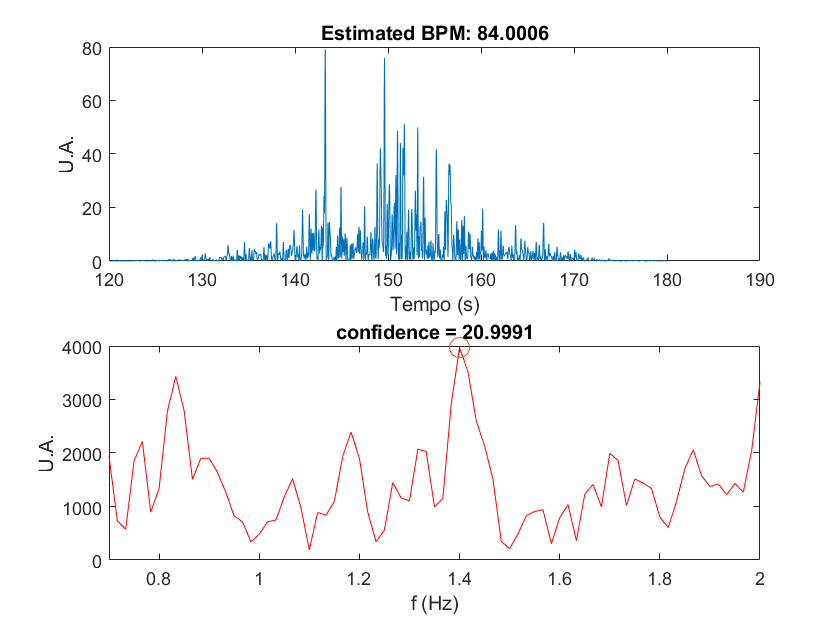

--------------------------------------------------------------------------


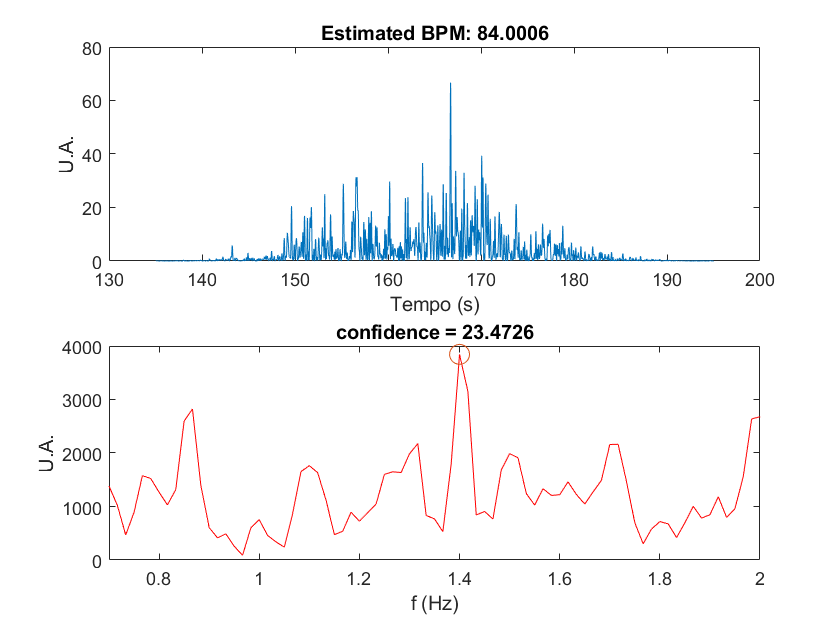

--------------------------------------------------------------------------


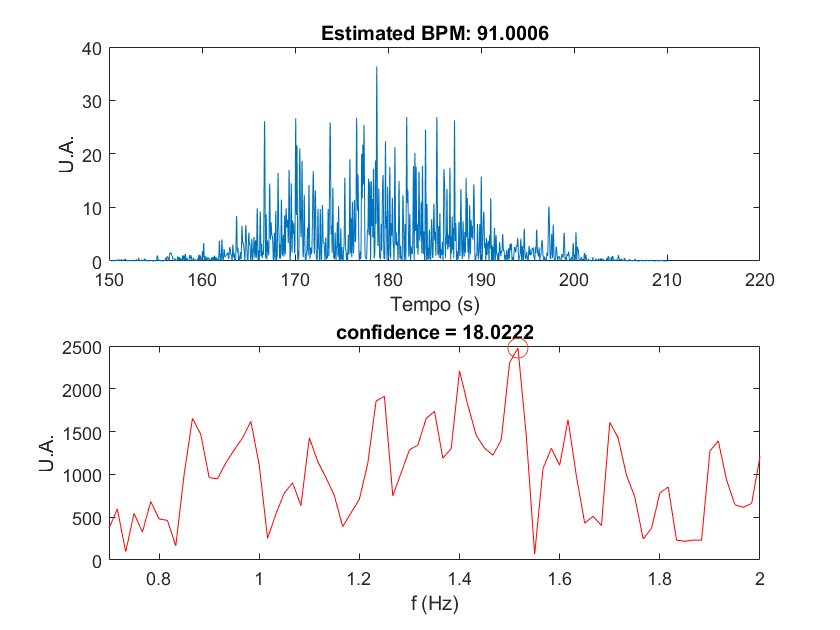

--------------------------------------------------------------------------


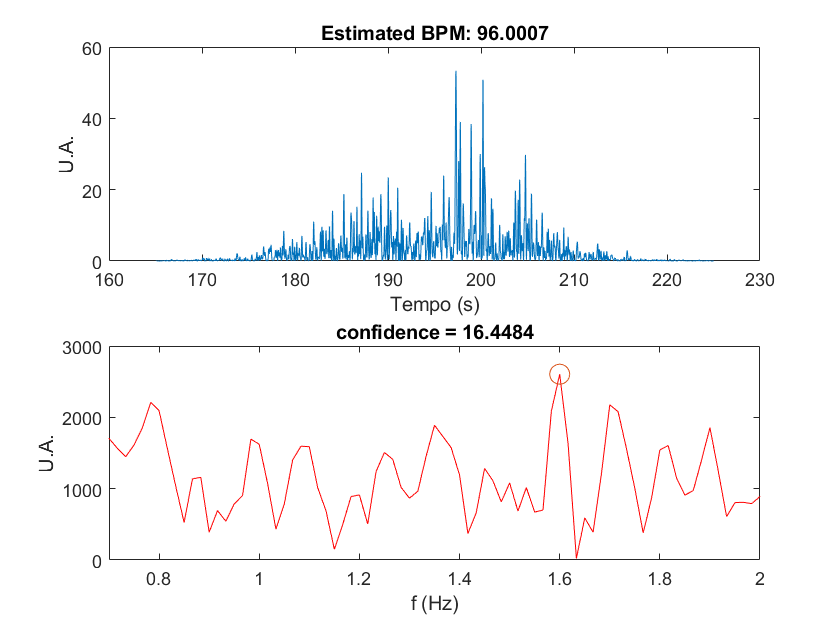

--------------------------------------------------------------------------


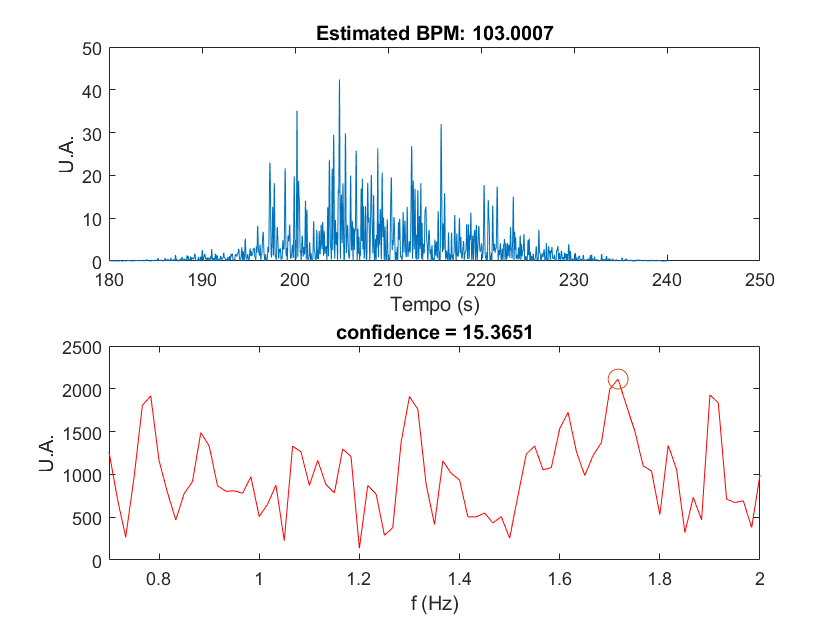

--------------------------------------------------------------------------


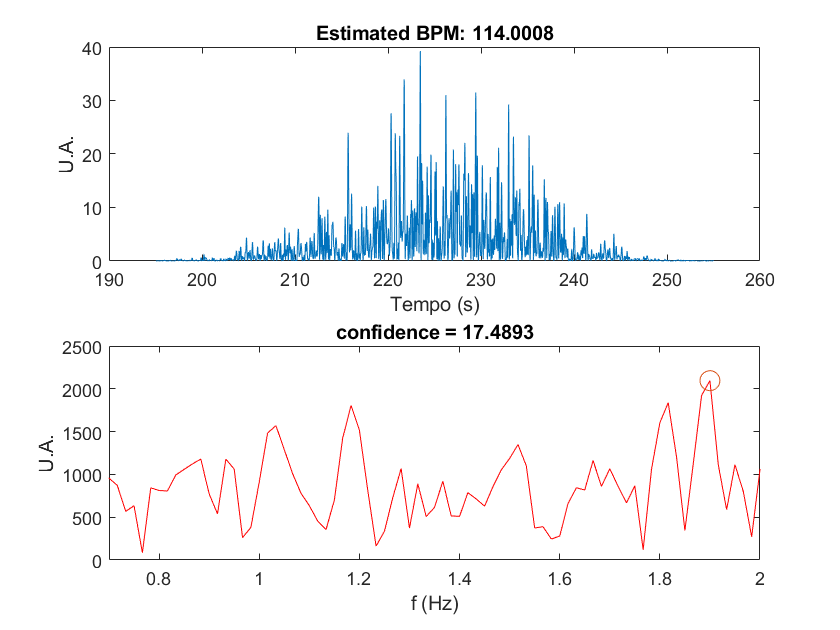

--------------------------------------------------------------------------


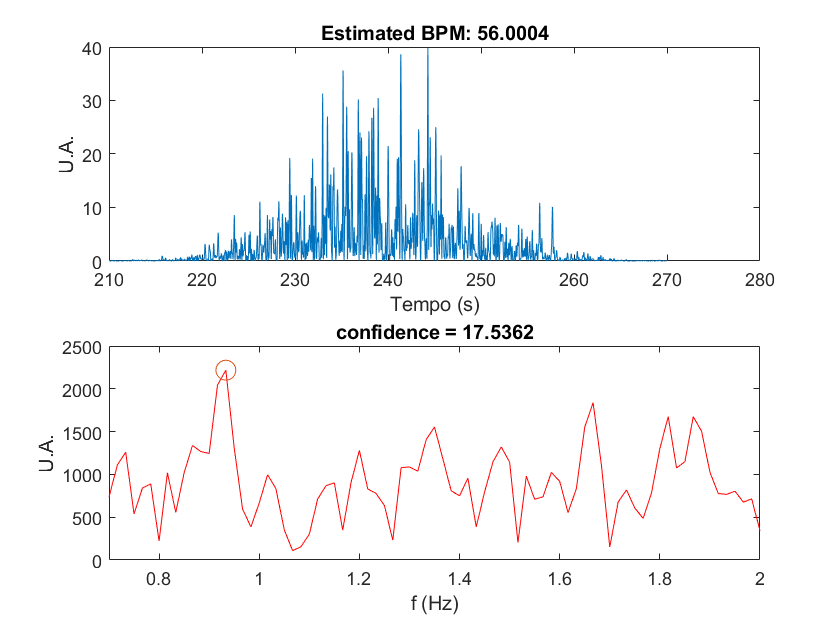

--------------------------------------------------------------------------


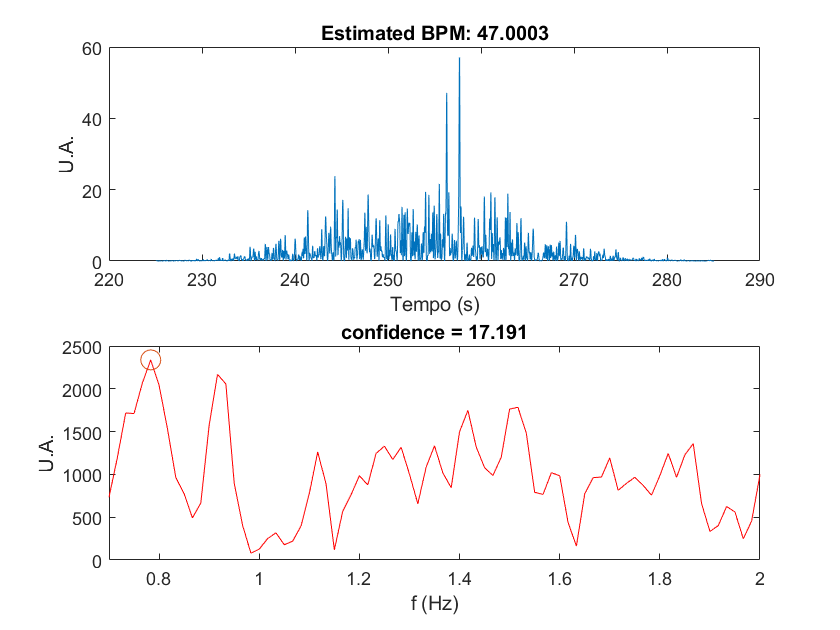

--------------------------------------------------------------------------


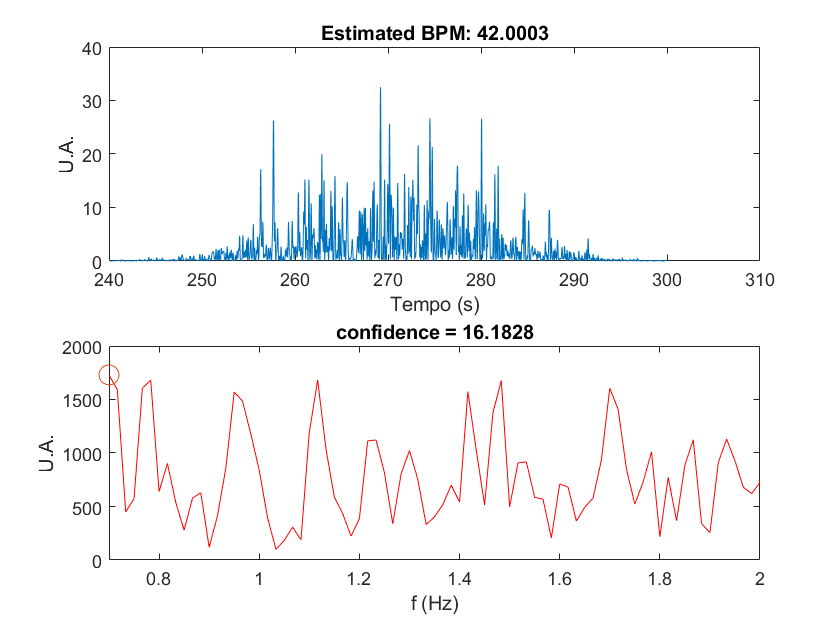

--------------------------------------------------------------------------


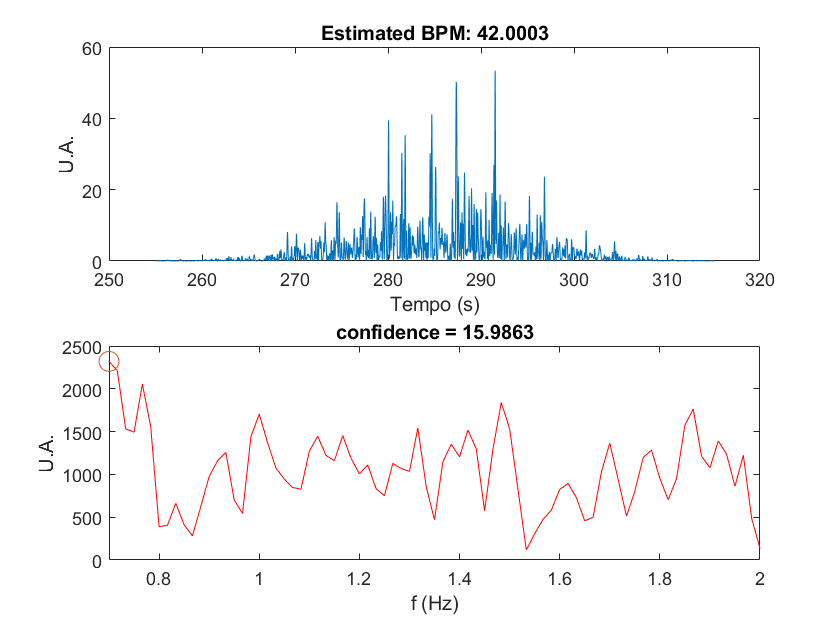

--------------------------------------------------------------------------


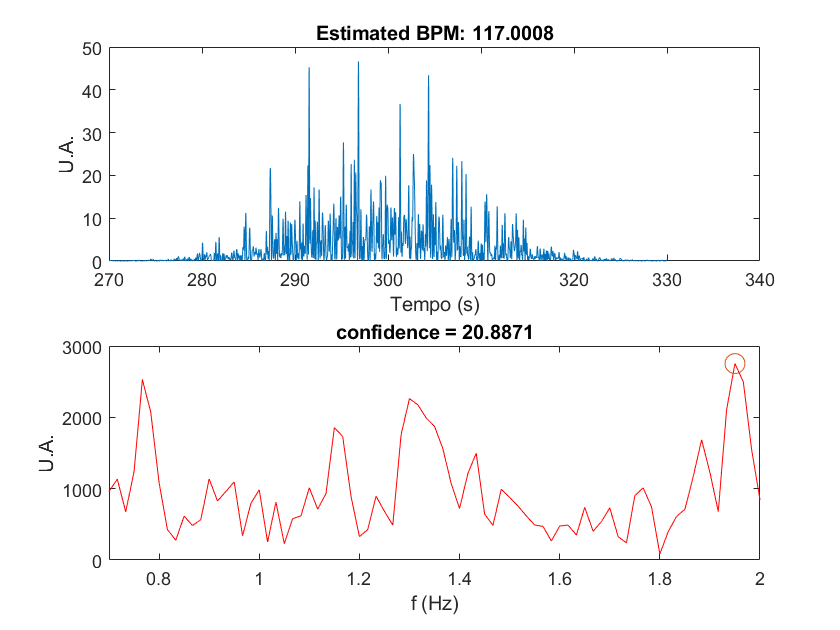

--------------------------------------------------------------------------


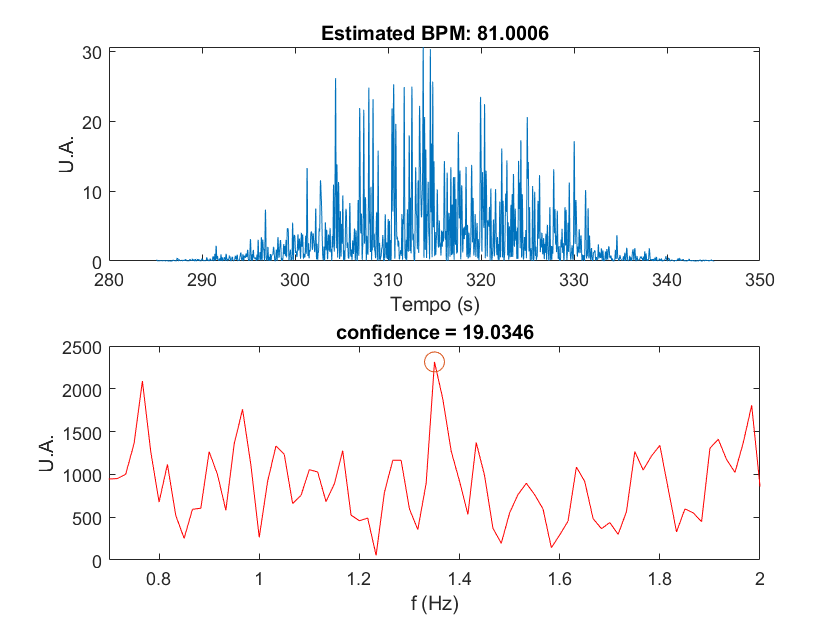

--------------------------------------------------------------------------


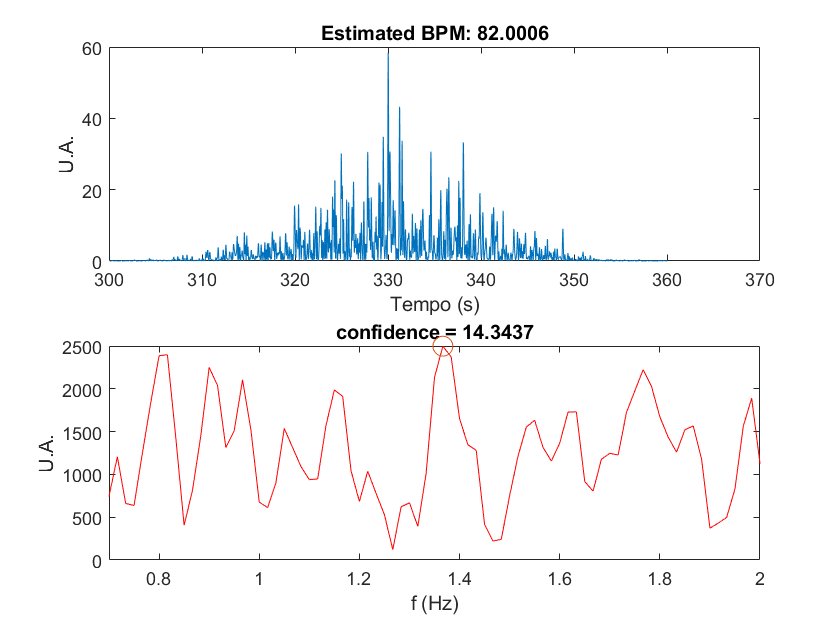

--------------------------------------------------------------------------


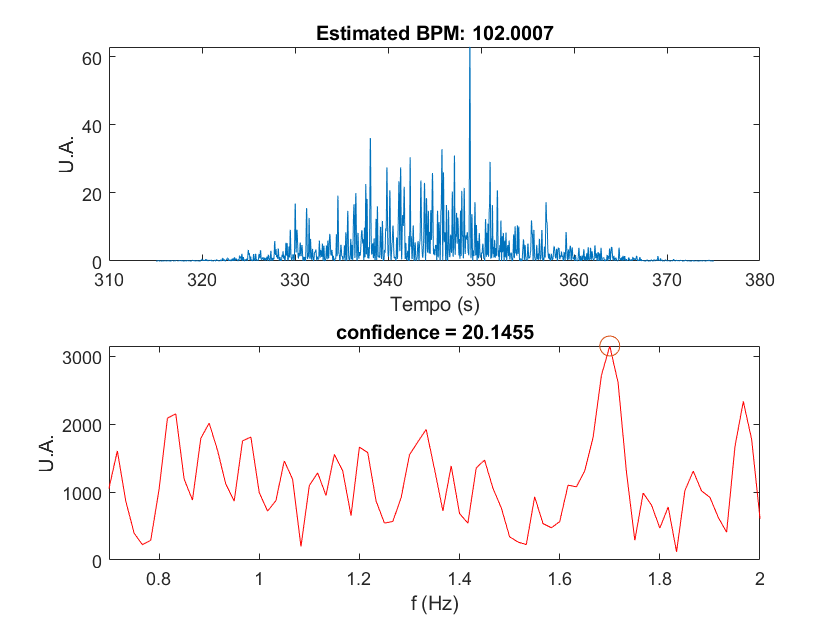

--------------------------------------------------------------------------


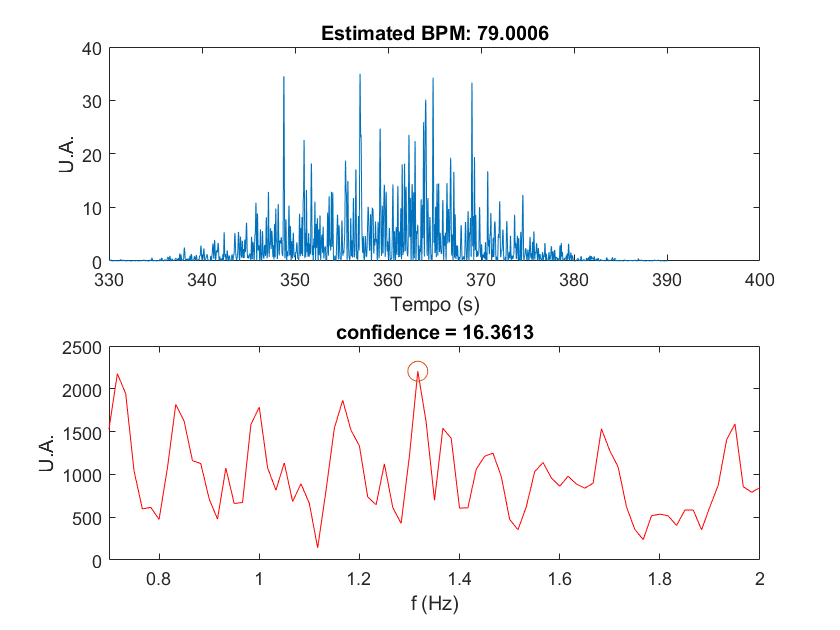

--------------------------------------------------------------------------


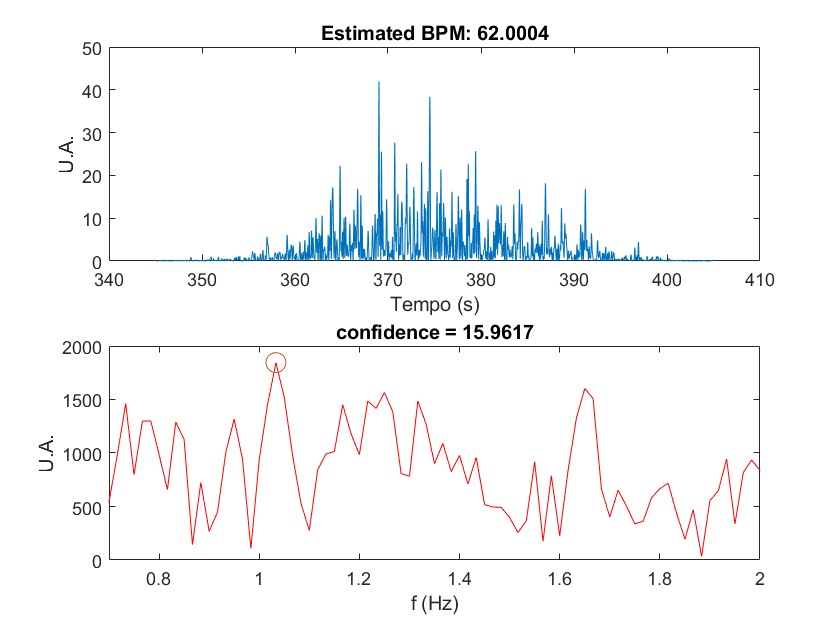

--------------------------------------------------------------------------


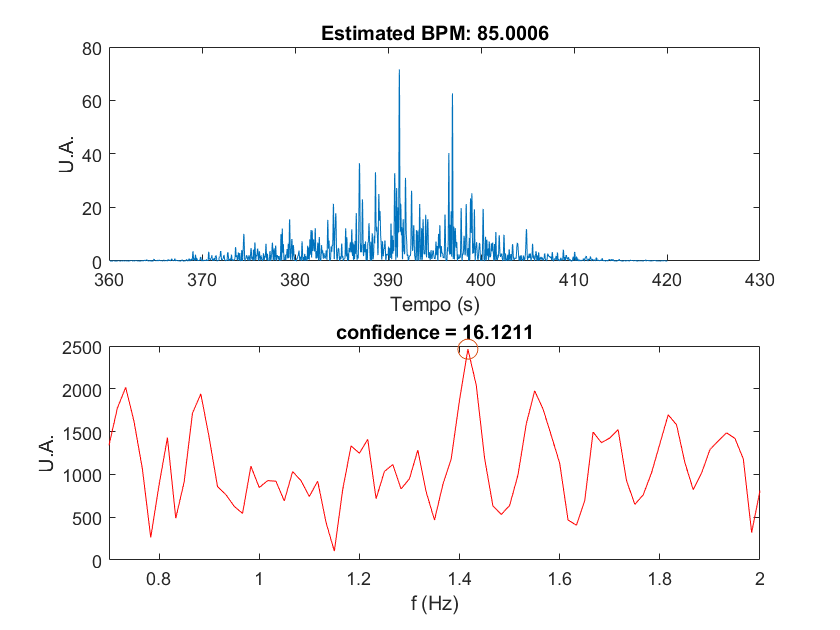

--------------------------------------------------------------------------


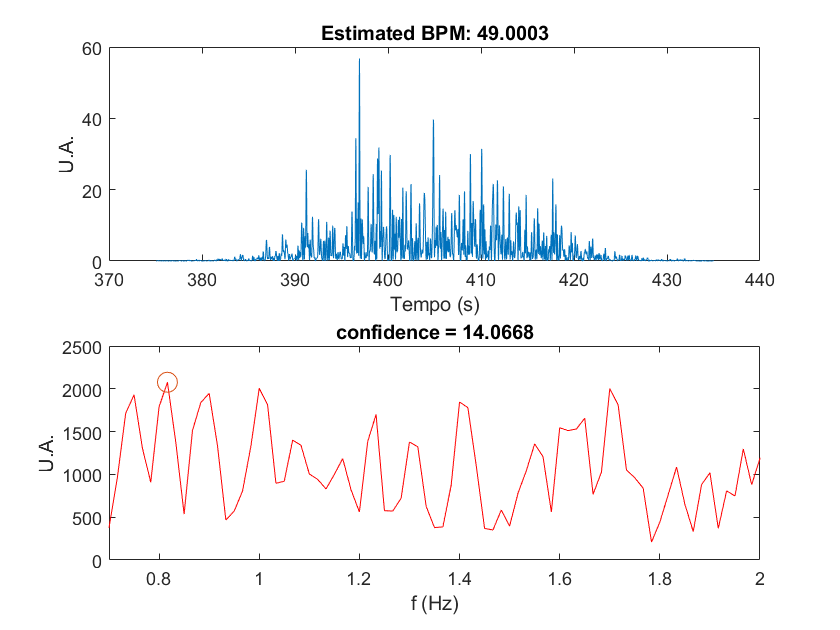

--------------------------------------------------------------------------



figure
for count = 1:n
    figure
    fft_cut = fft_data(1:numel(f_segment),count);
    [M, I] = max(abs(fft_cut(index_7:index_100))*2);
    bpms(count) = f_segment(I+index_7-1)*60;
    
    subplot(211)
    plot(time_array(:,count),ht_data(:,count))
    title("Estimated BPM: "+bpms(count))
    xlabel("Tempo (s)"),ylabel("U.A.")
    
    conf = confidence(fft_cut,f_segment,0.7,2);
    subplot(212)
    if conf > 25
        plot(f_segment, abs(fft_cut)*2)
    else
        plot(f_segment, abs(fft_cut)*2, "r")
    end
    xlim([0.7, 2])
    title("confidence = " + conf)
    xlabel("f (Hz)"),ylabel("U.A.")
    
    hold on
    plot(f_segment(I+index_7-1), M, 'o', 'MarkerSize', 10)
    disp("--------------------------------------------------------------------------")
end